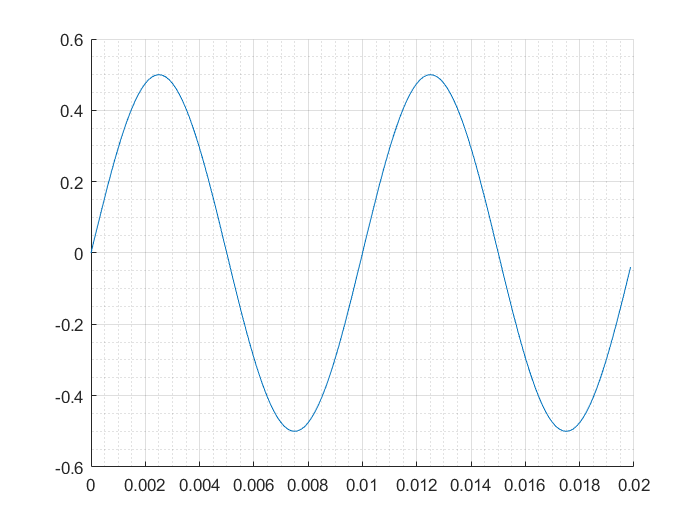

clc;
close all;
clear all;

fs = 8000;
Ts = 1/fs;

A  = 0.5;
f  = 100;
T  = 1/f;
P  = 2;         % periods ...

N  = P*T/Ts;
n  = 0:1:N-1;

w0 = 2*pi*f/fs;

b  = [0,sin(w0)];
a  = [1,-2*cos(w0),1];

x    = zeros(1,N);
y    = zeros(1,N);

x(1) = A; 

y = filter(b,a,x);

fig = figure;
set(fig,'color','w');

plot(n*Ts,y);
box off;
grid on; grid minor;

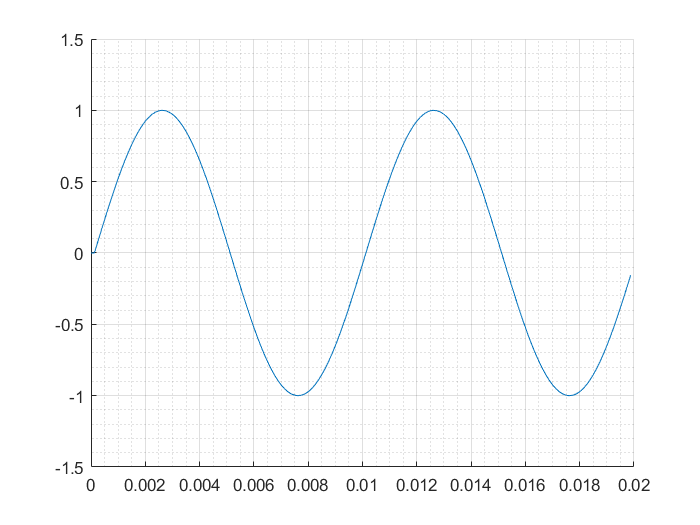


% now we are skipping the MATLAB internal 'filter' function ...
x1    = zeros(1,N);
y1    = zeros(1,N);
x1(2) = 1;

for i = 3:N
   y1(i) = sin(w0)*x1(i-1)+2*cos(w0)*y1(i-1)-y1(i-2);
end

fig = figure;
set(fig,'color','w');
plot(n*Ts,y1);
box off;
grid on; grid minor;

a = sin(w0)

a = 0.0785

b = 2*cos(w0)

b = 1.9938

c = 1

c = 1


CS = 2;

a_sc = a/CS

a_sc = 0.0392

b_sc = b/CS

b_sc = 0.9969

c_sc = c/CS

c_sc = 0.5000

S     = 2;
x2    = zeros(1,N);
x2(2) = 1; 
x2    = x2./S;
y2    = zeros(1,N);

for i = 3:N
   y2(i) = a_sc*x2(i-1)+b_sc*y2(i-1)-c_sc*y2(i-2);
   y2(i) = y2(i)*CS;
end

y2 = y2.*S;

fig = figure;
set(fig,'color','w');
plot(n*Ts,y2);
box off;
grid on; grid minor;

a_scq = fi(a_sc,1,16,15);
b_scq = fi(b_sc,1,16,15);
c_scq = fi(c_sc,1,16,15);
 test_a = fi(0.5,1,16,15)

test_a =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 15

 test_b = fi(0.5,1,16,15)

test_b =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 15

 test_c = test_a*test_b

test_c =     0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 32
        FractionLength: 30